N=100;
Btrue=[1 2 3]

Btrue =      1     2     3


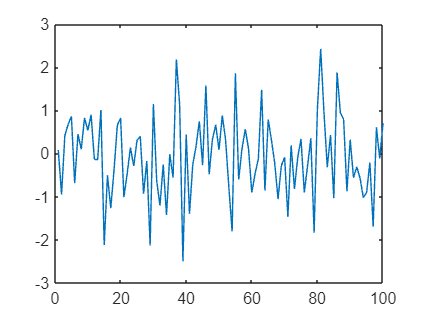

Atrue=[1 -0.75 0.25];
x=randn(N,1);
figure(1), plot(x)

y=filter(Btrue,Atrue,x);
P=2;
Q=2;
L=max(P,Q);
yvec = y((L+1):N);
yFirstCol = y(L:(N-1));
yFirstRow = y(L:(-1):(L-P+1));
xFirstCol = x((L+1):N);
xFirstRow = x((L+1):(-1):(L-Q+1));
X=toeplitz(xFirstCol,xFirstRow);
Y=toeplitz(yFirstCol,yFirstRow);
D=[Y X];
theta = pinv(D)*yvec

theta =     0.7500
   -0.2500
    1.0000
    2.0000
    3.0000
